## 2024 Presidental Debate Text and Sentiment Analysis

Written in MATLAB R2024a

Sources

- Transcript: [https://abcnews.go.com/Politics/harris-trump-presidential-debate-transcript/story?id=113560542](https://abcnews.go.com/Politics/harris-trump-presidential-debate-transcript/story?id=113560542)

- What is VADER: https://medium.com/@rslavanyageetha/vader-a-comprehensive-guide-to-sentiment-analysis-in-python-c4f1868b0d2e

## Read and preprocess the text

% Read the text
fileID = fopen('debate_transcript.txt', 'r');

% Create vectors of Harris and Trump text
harris_lines = {};
trump_lines = {};
moderator_lines = {};

% Read the file line by line
while ~feof(fileID)
    % Read a line from the file
    line = fgetl(fileID);
    
    % Check if its a Harris line
    if startsWith(line, 'VICE PRESIDENT KAMALA HARRIS:')
        % Extract the text
        text = strtrim(line(length('VICE PRESIDENT KAMALA HARRIS:')+1:end));
        
        % Add the extracted text to the cell array
        harris_lines{end+1} = text; 
    % Check if it's a Trump line
    elseif startsWith(line, 'FORMER PRESIDENT DONALD TRUMP:')
        % Extract the text
        text = strtrim(line(length('FORMER PRESIDENT DONALD TRUMP:')+1:end));
        
        % Add the extracted text to the cell array
        trump_lines{end+1} = text;
    % Check if it's a line from the moderators
    elseif startsWith(line, 'LINSEY DAVIS:')
        % Extract the text
        text = strtrim(line(length('LINSEY DAVIS:')+1:end));
        
        % Add the extracted text to the cell array
        moderator_lines{end+1} = text;
    elseif startsWith(line, 'DAVID MUIR:')
        % Extract the text
        text = strtrim(line(length('DAVID MUIR:')+1:end));
        
        % Add the extracted text to the cell array
        moderator_lines{end+1} = text;  
    end
end

% Close the file
fclose(fileID);

% Convert to tokens
harris_tokens = tokenizedDocument(harris_lines);
trump_tokens = tokenizedDocument(trump_lines);

## Basic Stats

disp(strcat("Harris Word count: ", num2str(length(strsplit(strjoin(harris_lines))))))

Harris Word count: 5866


disp(strcat("Harris Paragraphs: ", num2str(length(harris_lines))))

Harris Paragraphs: 34


disp(strcat("Trump Word count: ", num2str(length(strsplit(strjoin(trump_lines))))))

Trump Word count: 8057


disp(strcat("Trump Paragraphs: ", num2str(length(trump_lines))))

Trump Paragraphs: 74


disp(strcat("Moderator Word count: ", num2str(length(strsplit(strjoin(moderator_lines))))))

Moderator Word count: 3105


disp(strcat("Moderator Paragraphs: ", num2str(length(moderator_lines))))

Moderator Paragraphs: 108


## Word Clouds

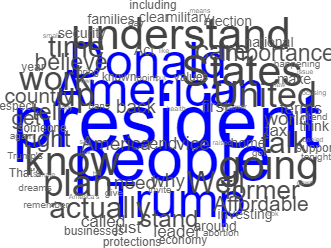

% Display Harris text (blue scale)
wordcloud(harris_lines, "HighlightColor", [0 0 1]); % Requires text analyics toolbox

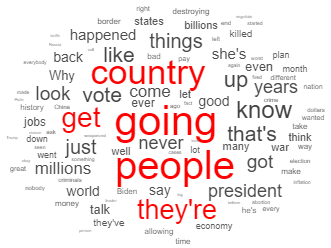


% Display Trump text (red scale)
wordcloud(trump_lines, "HighlightColor", [1 0 0]); % Requires text analyics toolbox

## Sentiment Analysis

% Display Harris vader data
harris_sentiment_vader = vaderSentimentScores(harris_tokens);
disp(strcat("Average Harris vader sentiment: ", num2str(mean(harris_sentiment_vader))));

Average Harris vader sentiment: 0.35634


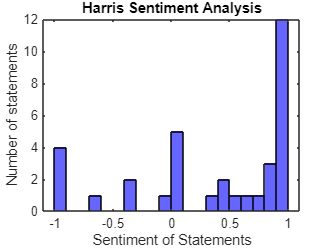

histogram(harris_sentiment_vader, "BinWidth", 0.1, "FaceColor", [0 0 1]);
title('Harris Sentiment Analysis');
xlabel('Sentiment of Statements');
ylabel('Number of statements');

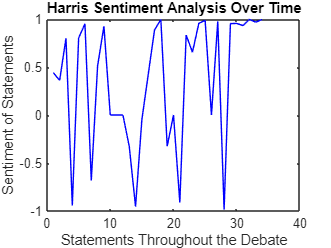

plot(harris_sentiment_vader, "Color", [0 0 1]);
title('Harris Sentiment Analysis Over Time');
xlabel('Statements Throughout the Debate');
ylabel('Sentiment of Statements');


% Display Trump vader data
trump_sentiment_vader = vaderSentimentScores(trump_tokens);
disp(strcat("Average Trump vader sentiment: ", num2str(mean(trump_sentiment_vader))));

Average Trump vader sentiment: -0.16691


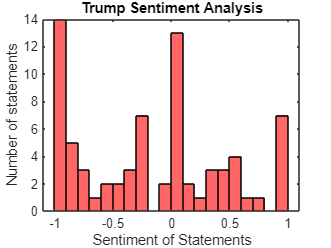

histogram(trump_sentiment_vader, "BinWidth", 0.1, "FaceColor", [1 0 0]);
title('Trump Sentiment Analysis');
xlabel('Sentiment of Statements');
ylabel('Number of statements');

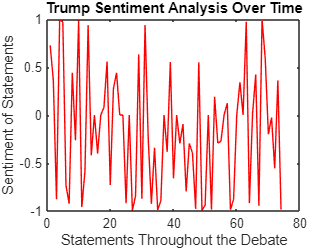

plot(trump_sentiment_vader, "Color", [1 0 0]);
title('Trump Sentiment Analysis Over Time');
xlabel('Statements Throughout the Debate');
ylabel('Sentiment of Statements');

## Emotion Analysis

        Emotion         Score
    ________________    _____

    {'anger'       }      87 
    {'anticipation'}     127 
    {'disgust'     }      59 
    {'fear'        }     127 
    {'joy'         }      76 
    {'sadness'     }      94 
    {'surprise'    }      65 
    {'trust'       }     256 



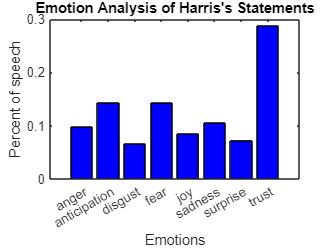

% Repeat with emotions using the library
emotion_display(harris_lines, 'Harris', [0 0 1]);

        Emotion         Score
    ________________    _____

    {'anger'       }     141 
    {'anticipation'}     143 
    {'disgust'     }      74 
    {'fear'        }     173 
    {'joy'         }     119 
    {'sadness'     }     146 
    {'surprise'    }      86 
    {'trust'       }     243 



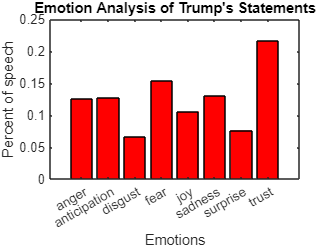

emotion_display(trump_lines, 'Trump', [1 0 0]);